## Test function: Rosenbrock function

% x0 = [-1.2; 1];  % starting point 1 (medium)
x0 = [1.2; 1.2];  % starting point 2 (easy)
% x0 = [5; 5];  % another possible choice (hard)

% Rosenbrock function
f = @(x) 100*(x(2,:) - x(1,:).^2).^2 + (1 - x(1,:)).^2;  
% Gradient
gradf = @(x) [400*x(1,:).^3-400*x(1,:).*x(2,:)+2*x(1,:)-2 ; 200*(x(2,:)-x(1,:).^2)]; 

% Expected solution
x_sol = [1; 1];

## Steepest descent method

### Parameters 

load('forcing_terms.mat')

kmax = 100000;  % maximum number of iterations
tolgrad = 1e-7;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 1;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, tolgrad, c1, rho, btmax)

parameters = 1×5 table
    kmax     tolgrad      c1      rho    btmax
    _____    _______    ______    ___    _____

    1e+05     1e-07     0.0001    0.5     500 


[xk, fk, gradfk_norm, k, xseq, btseq, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt_plot(x0, x_sol, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


tail(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm, errf_final, totalTimeCost)

results_1 = 1×5 table
        fk          k      gradfk_norm    errf_final    totalTimeCost
    __________    _____    ___________    __________    _____________

    6.1727e-15    15851    9.9773e-08     6.1727e-15       0.28441   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     0.43098             0      0.037279  
    0.019689      -0.14432      0.038766  
    0.012615      -0.10163      0.063611  
    0.012413       -1.5689      0.064033  
      0.0124       0.26606      0.066771  
    0.012391        4.6527      0.067248  
    0.012387     -0.019436       0.06856  
    0.012351       -133.55      0.068668  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

    6.2427e-15       2.8047         0.2843  
    6.2325e-15      0.38421        0.28432  
    6.2225e-15       2.5338        0.28434  
    6.2124e-15      0.42069        0.28435  
    6.2024e-15       2.3178        0.28437  
    6.1925e-15      0.45589        0.28438  
    6.1826e-15       2.1422         0.2844  
    6.1727e-15            0        0.28441  


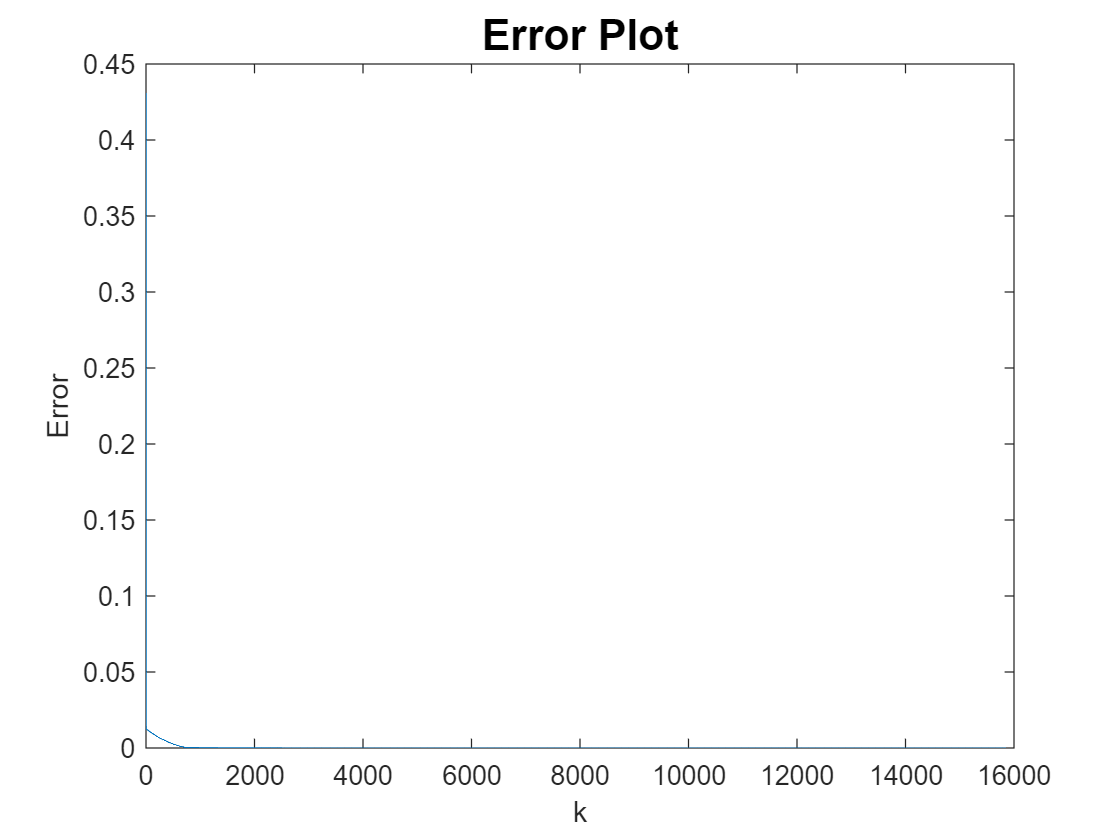

plot(1:k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

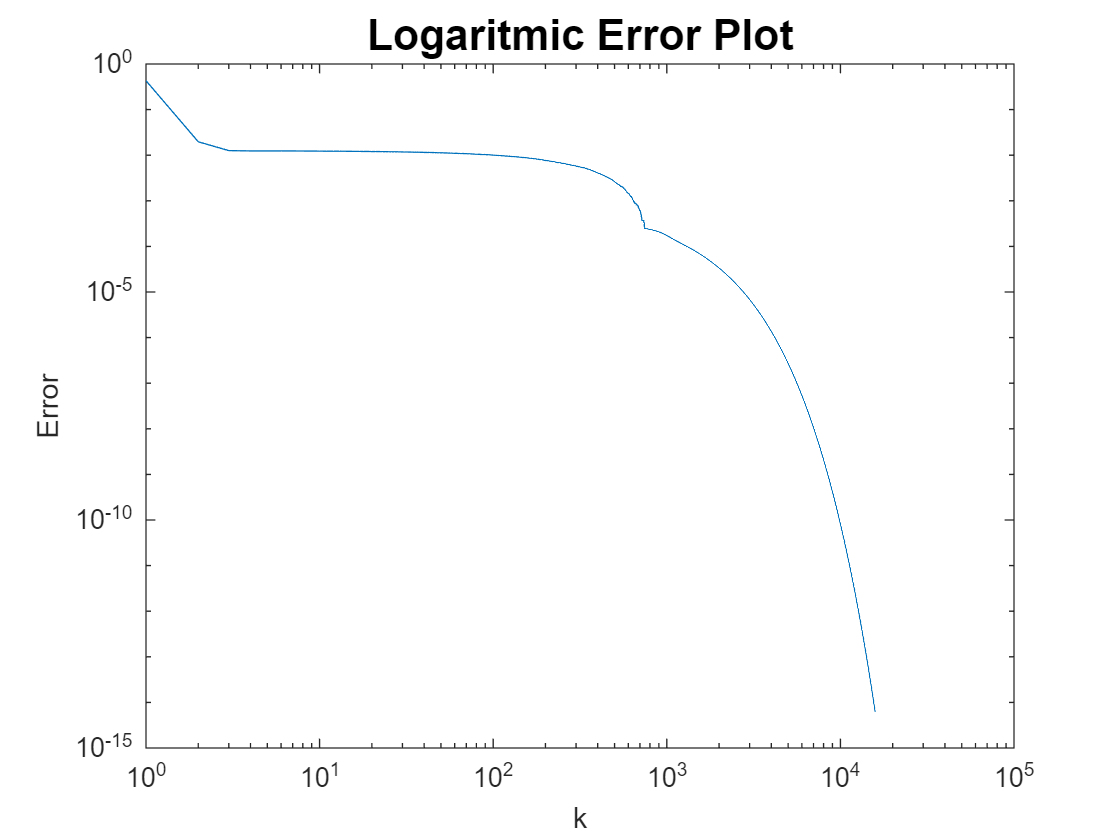

loglog(1:k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

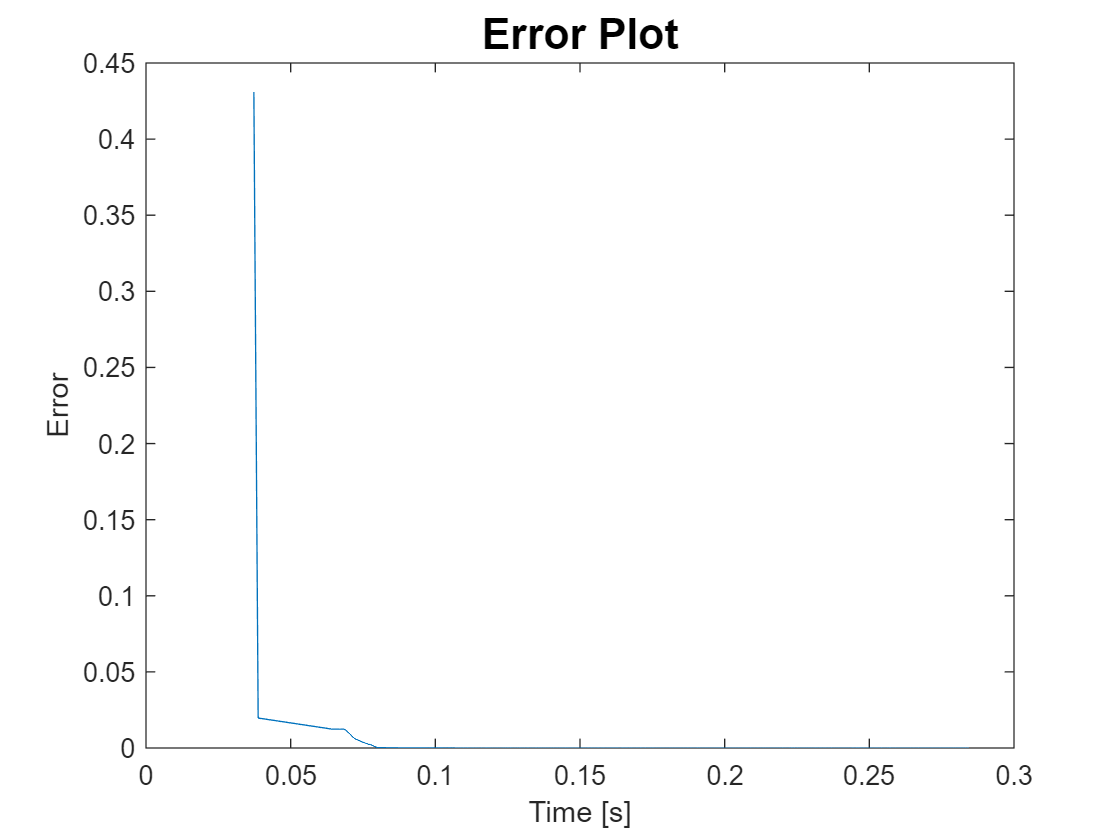

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

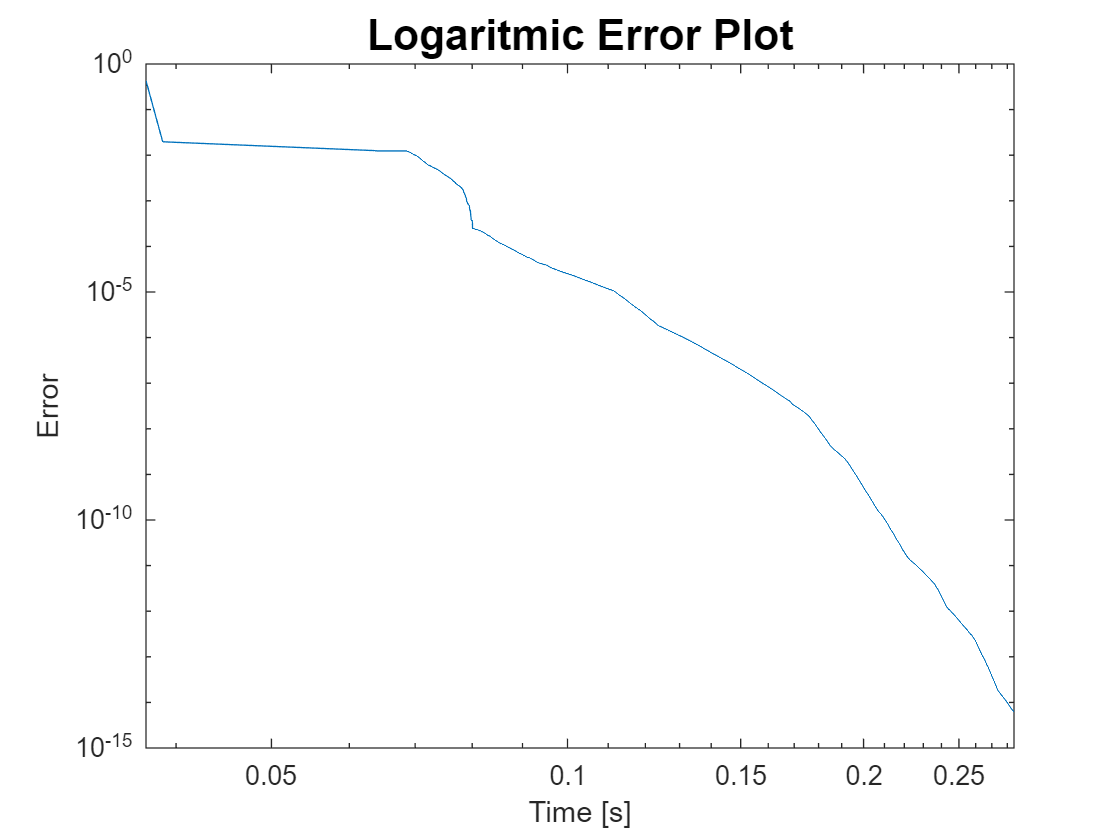

loglog(timeCostseq, err_fseq)
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

#### Plots

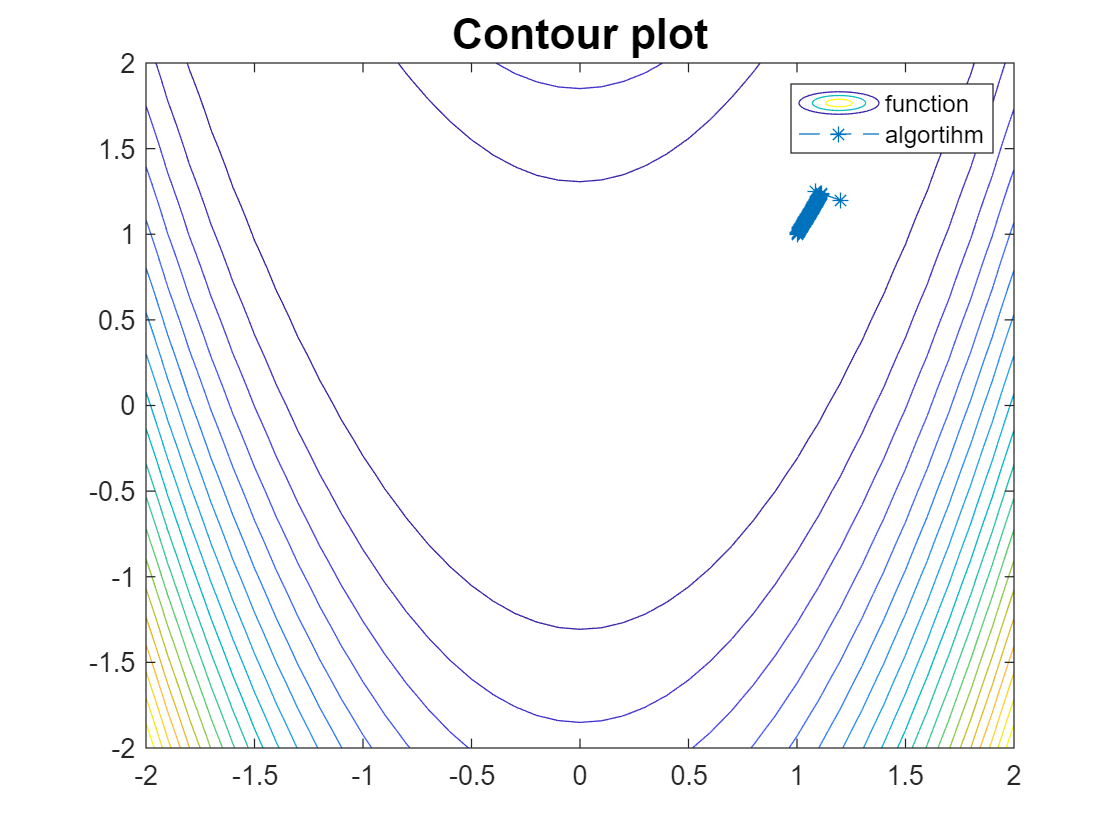

% Preliminaries
x = -2:0.1:2;
y = -2:0.1:2;
[X,Y] = meshgrid(x, y);  % creation of the meshgrid for the contour-plot
f_meshgrid = @(X,Y) reshape(f([X(:),Y(:)]'),size(X));
Z = f_meshgrid(X, Y);  % ("elegant") computation of the values of f for each point of the mesh

% Contour plot
fig1 = figure(); 
contour(X, Y, Z, 20);  % f(xseq)
hold on
title('Contour plot','FontSize',16)
plot([x0(1), xseq(1, :)], [x0(2), xseq(2, :)], '--*') 
legend('function', 'algortihm')
hold off

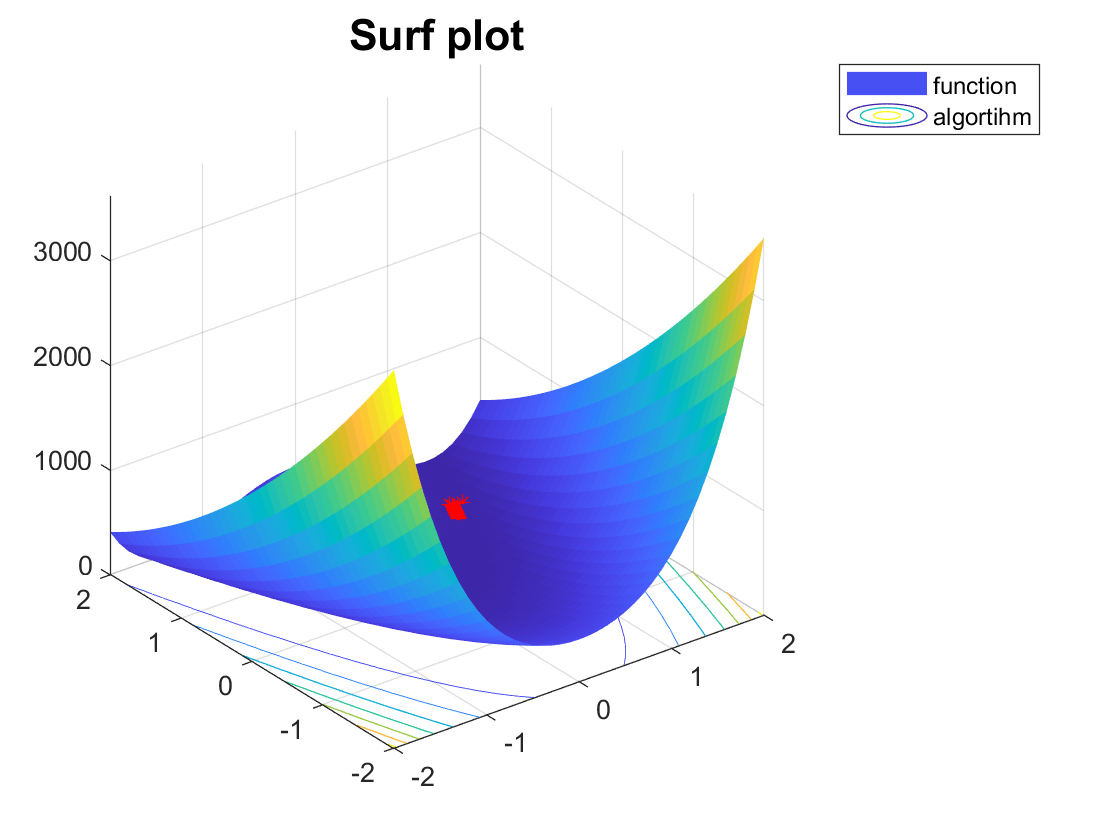

% Surf plot
fig3 = figure();  
surfc(X, Y, Z, 'EdgeColor', 'none')
% shading interp;
% colormap jet
hold on
title('Surf plot','FontSize',16)
plot3([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], [f(x0), f(xseq)], 'r--*')
% colorbar
legend('function', 'algortihm')
hold off

## Inexact Newton method

### Parameters

kmax = 100000;  % maximum number of iterations
tolgrad = 1e-6;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×6 table
    kmax     tolgrad    alpha0      c1      rho    btmax
    _____    _______    ______    ______    ___    _____

    1e+05     1e-06       1       0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, pk_itcount, xseq, btseq, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck_plot(x0, x_sol, f, gradf, Hessf, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


tail(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm, errf_final, totalTimeCost)

results_1 = 1×6 table
        fk        k    pk_itcount    gradfk_norm    errf_final    totalTimeCost
    __________    _    __________    ___________    __________    _____________

    5.5476e-18    9        13        1.0473e-07     5.5476e-18       0.1462    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

      0.053436             0       0.11017  
      0.012541        65.097       0.11499  
     0.0039323     0.0062375       0.12124  
     0.0026694        577.18       0.12725  
    0.00083899     -0.021154       0.14266  
    1.0709e-05       -90.098       0.14444  
    1.1376e-08    -0.0086153       0.14581  
    2.3526e-10       -236.27       0.14607  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

      0.012541        65.097       0.11499  
     0.0039323     0.0062375       0.12124  
     0.0026694        577.18       0.12725  
    0.00083899     -0.021154       0.14266  
    1.0709e-05       -90.098       0.14444  
    1.1376e-08    -0.0086153       0.14581  
    2.3526e-10       -236.27       0.14607  
    5.5476e-18             0        0.1462  


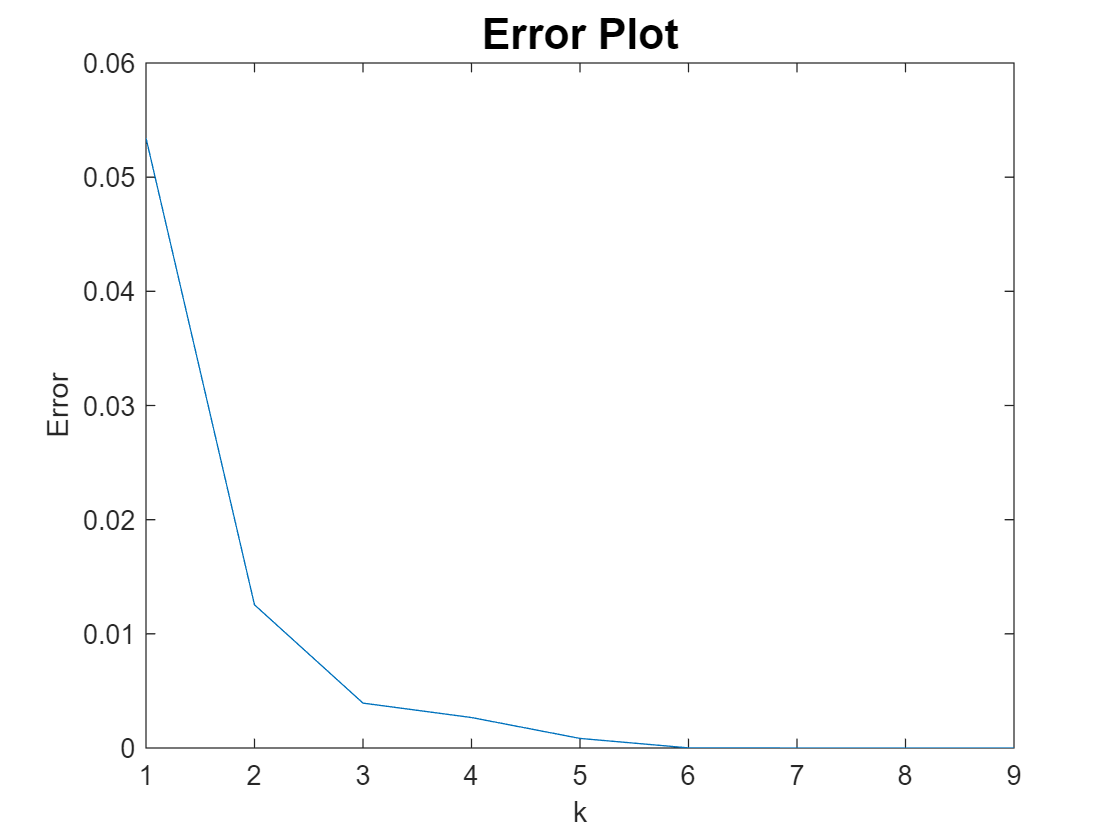

plot(1:k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

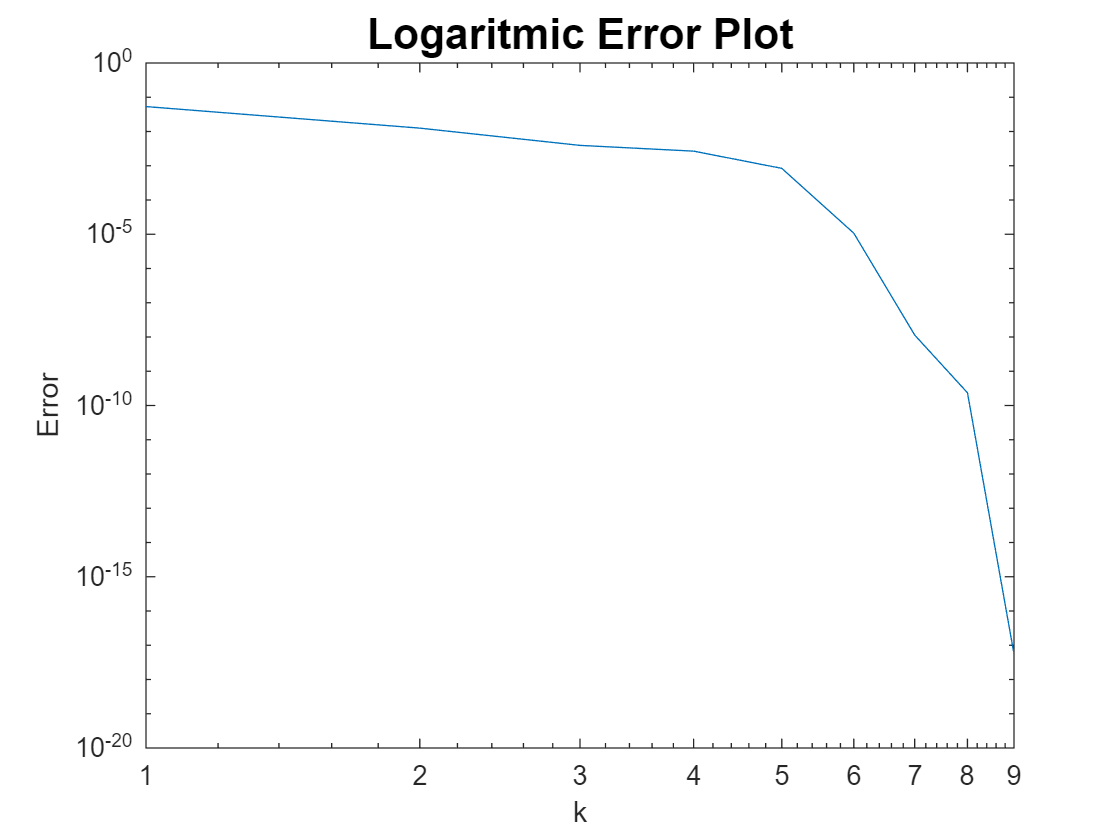

loglog(1:k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

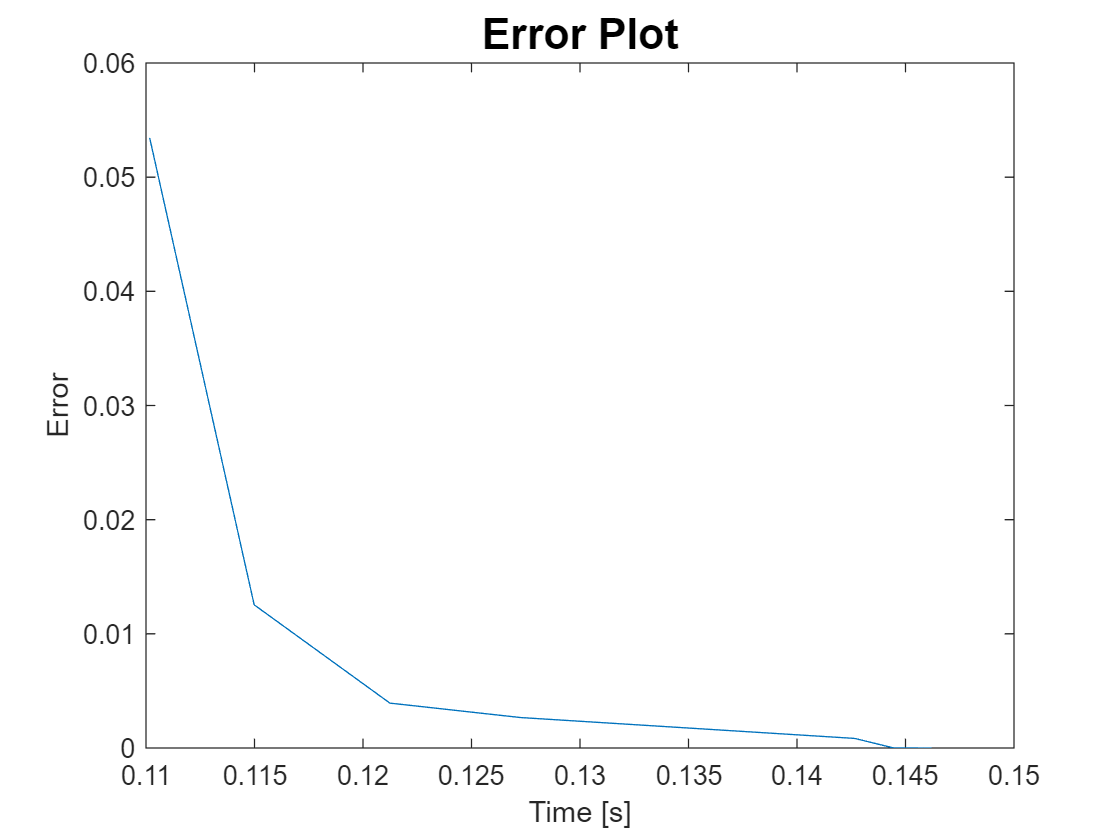

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

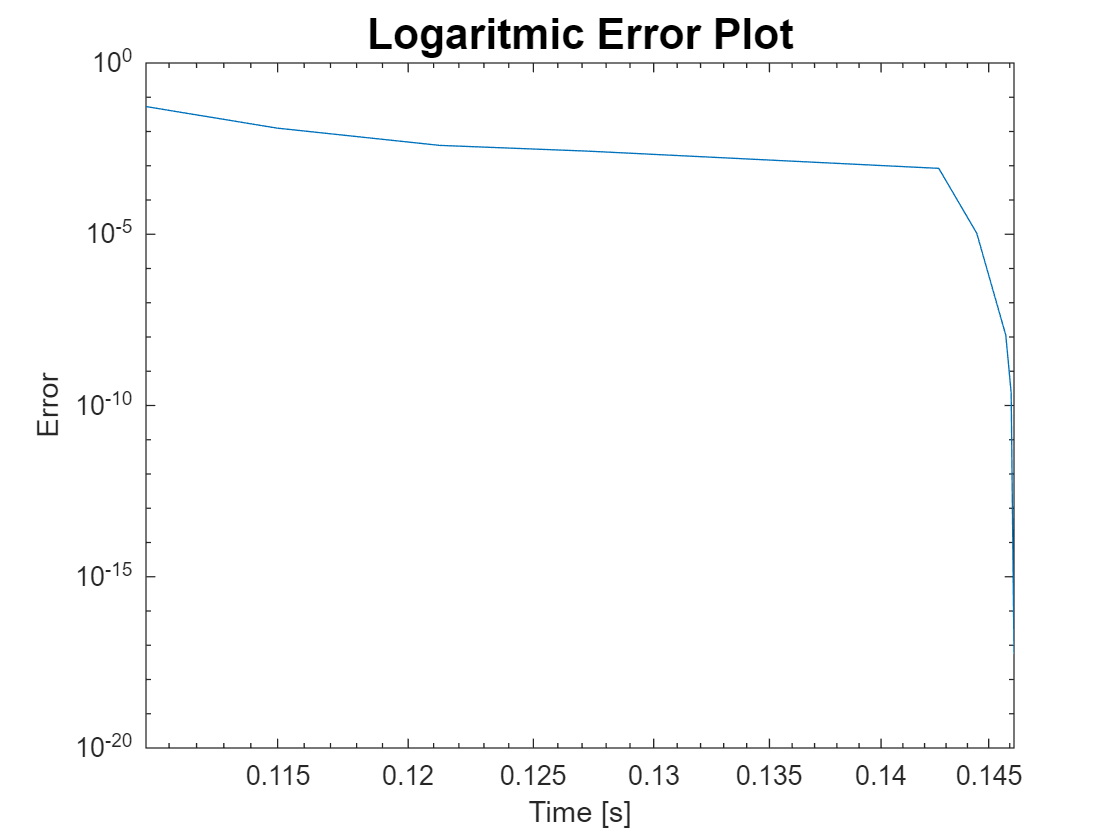

loglog(timeCostseq, err_fseq)
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

#### Plots

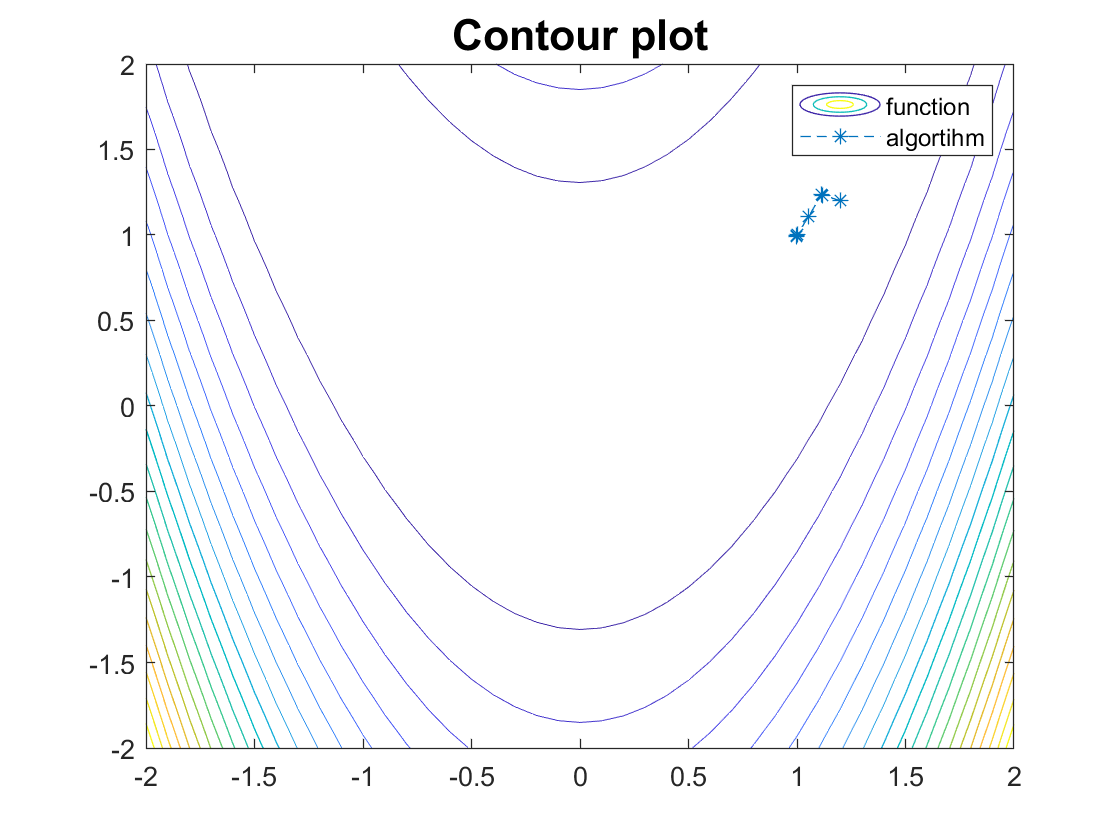

% Preliminaries
x = -2:0.1:2;
y = -2:0.1:2;
[X,Y] = meshgrid(x, y);  % creation of the meshgrid for the contour-plot
f_meshgrid = @(X,Y) reshape(f([X(:),Y(:)]'),size(X));
Z = f_meshgrid(X, Y);  % ("elegant") computation of the values of f for each point of the mesh

% Contour plot
fig1 = figure(); 
contour(X, Y, Z, 20);  % f(xseq)
hold on
title('Contour plot','FontSize',16)
plot([x0(1), xseq(1, :)], [x0(2), xseq(2, :)], '--*') 
legend('function', 'algortihm')
hold off

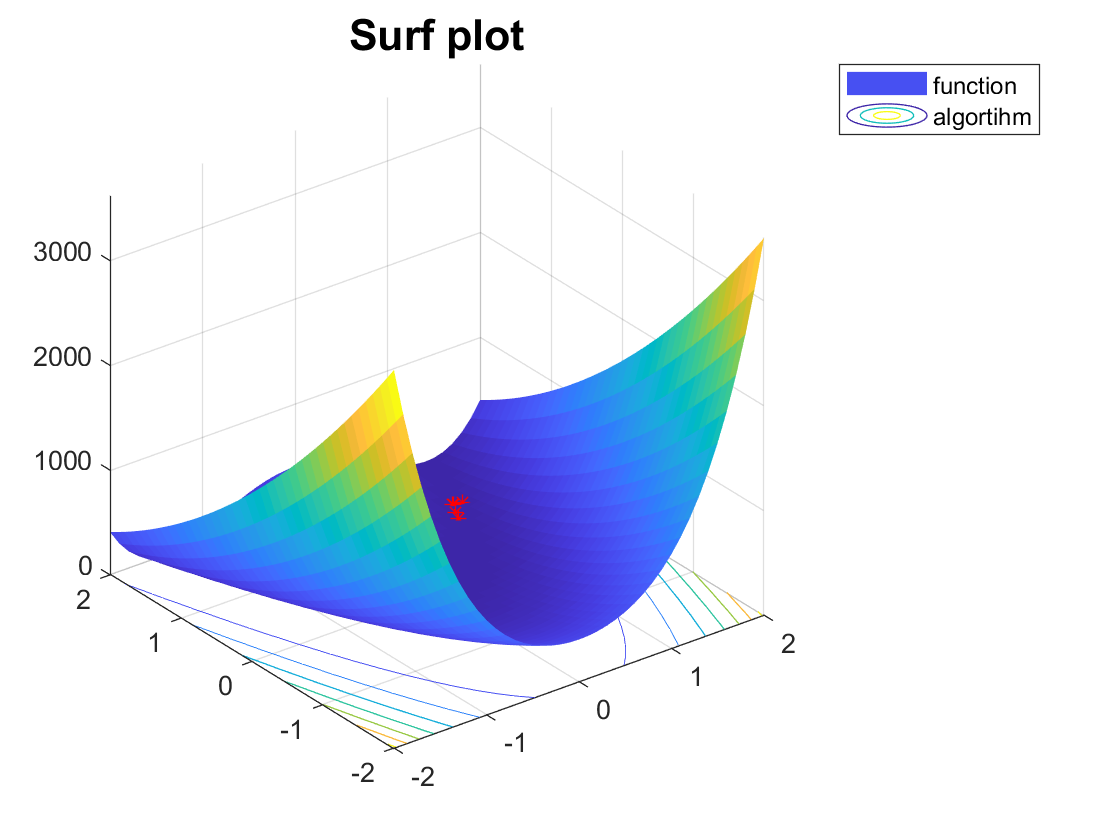

% Surf plot
fig3 = figure();  
surfc(X, Y, Z, 'EdgeColor', 'none')
% shading interp;
% colormap jet
hold on
title('Surf plot','FontSize',16)
plot3([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], [f(x0), f(xseq)], 'r--*')
% colorbar
legend('function', 'algortihm')
hold off

## Modified Newton method

### Parameters

kmax = 100000;  % maximum number of iterations
tolgrad = 1e-7;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×6 table
    kmax     tolgrad    alpha0      c1      rho    btmax
    _____    _______    ______    ______    ___    _____

    1e+05     1e-07       1       0.0001    0.5     500 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
[xk, fk, gradfk_norm, k, xseq, btseq, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    modnewton_bcktrck_plot(x0, x_sol, f, gradf, Hessf, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


tail(results_0, 8)

ans = 2×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  


errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm, errf_final, totalTimeCost)

results_1 = 1×5 table
        fk        k     gradfk_norm    errf_final    totalTimeCost
    __________    __    ___________    __________    _____________

    2.7087e-21    13    2.2908e-09     2.7087e-21       0.2383    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

       0.03637             0       0.17441  
       0.02456       -34.073       0.18262  
      0.012082        1.2148       0.19778  
     0.0091507       0.25082       0.21706  
     0.0034439        4.3924       0.22279  
     0.0012681        2.5493       0.22417  
    0.00041647     -0.055807       0.22678  
     8.351e-05       -17.062       0.22808  


tail(results_2, 8)

ans = 8×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

     0.0012681        2.5493       0.22417  
    0.00041647     -0.055807       0.22678  
     8.351e-05       -17.062       0.22808  
    6.1793e-06        3.0224       0.22842  
    1.4535e-07       0.22037       0.22876  
    3.4045e-10         5.532       0.22904  
    1.9566e-14        1.9561       0.23221  
    2.7087e-21             0        0.2383  


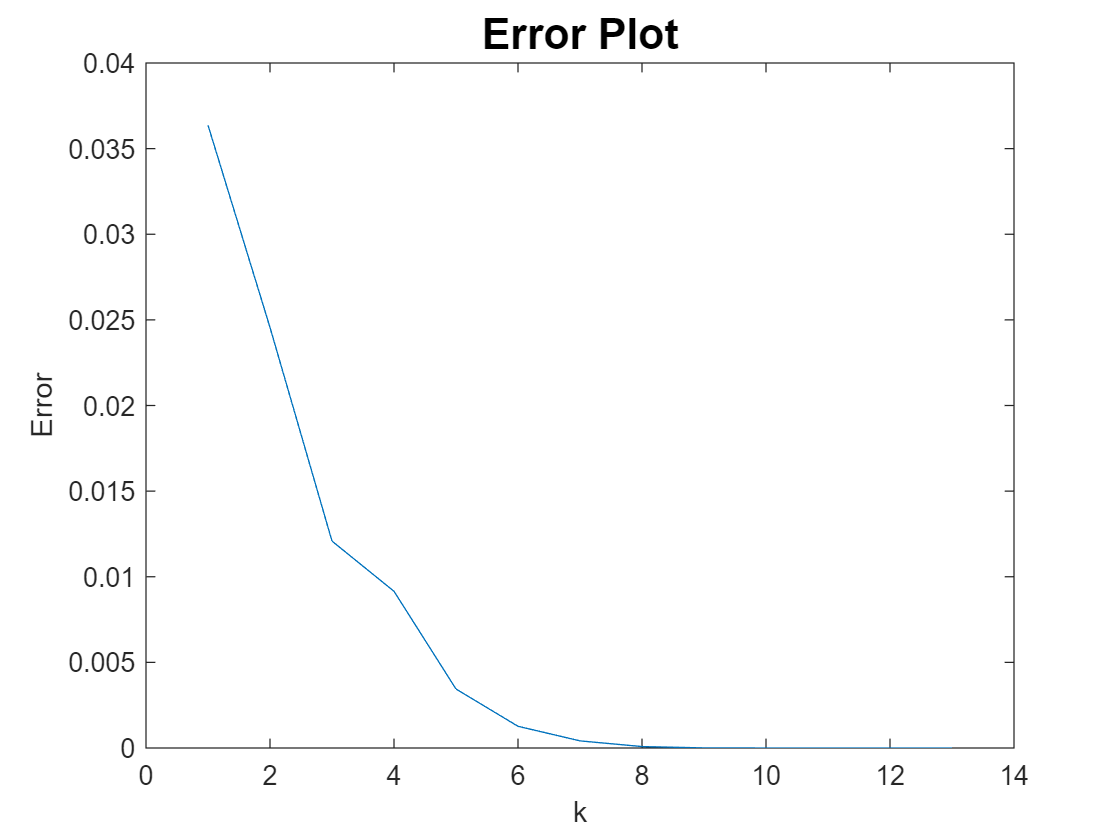

plot(1:k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

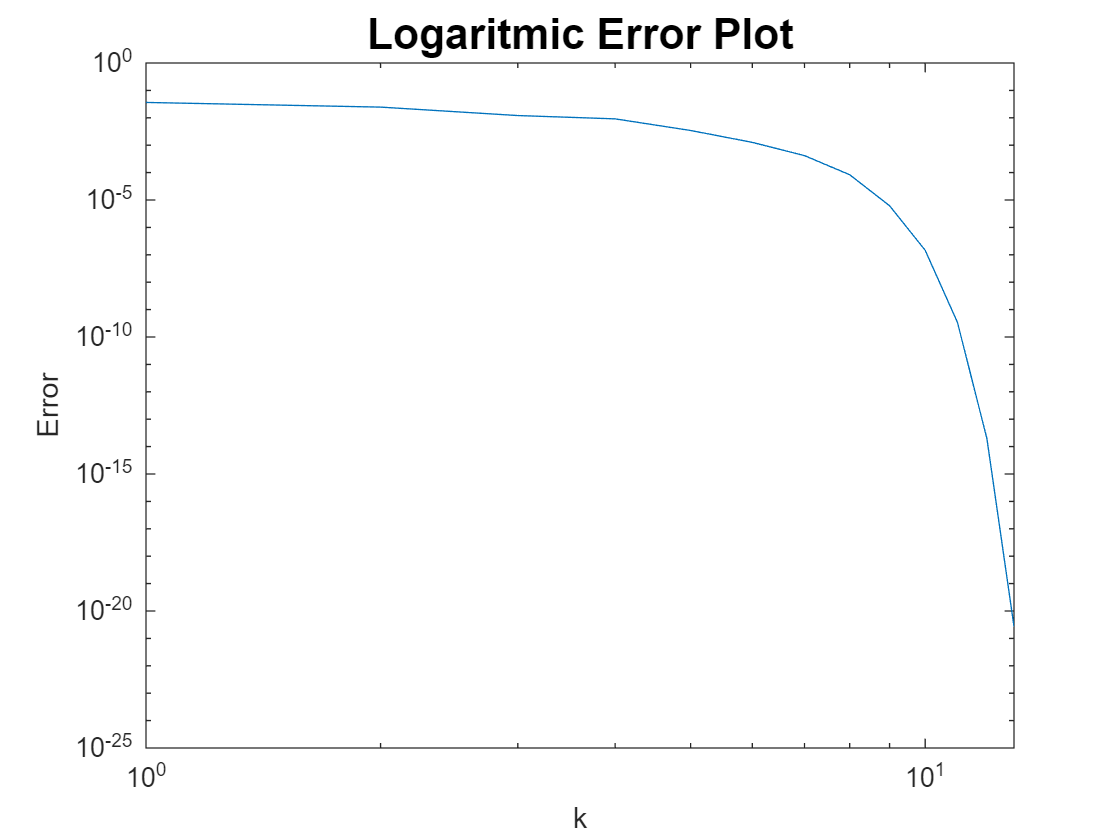

loglog(1:k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

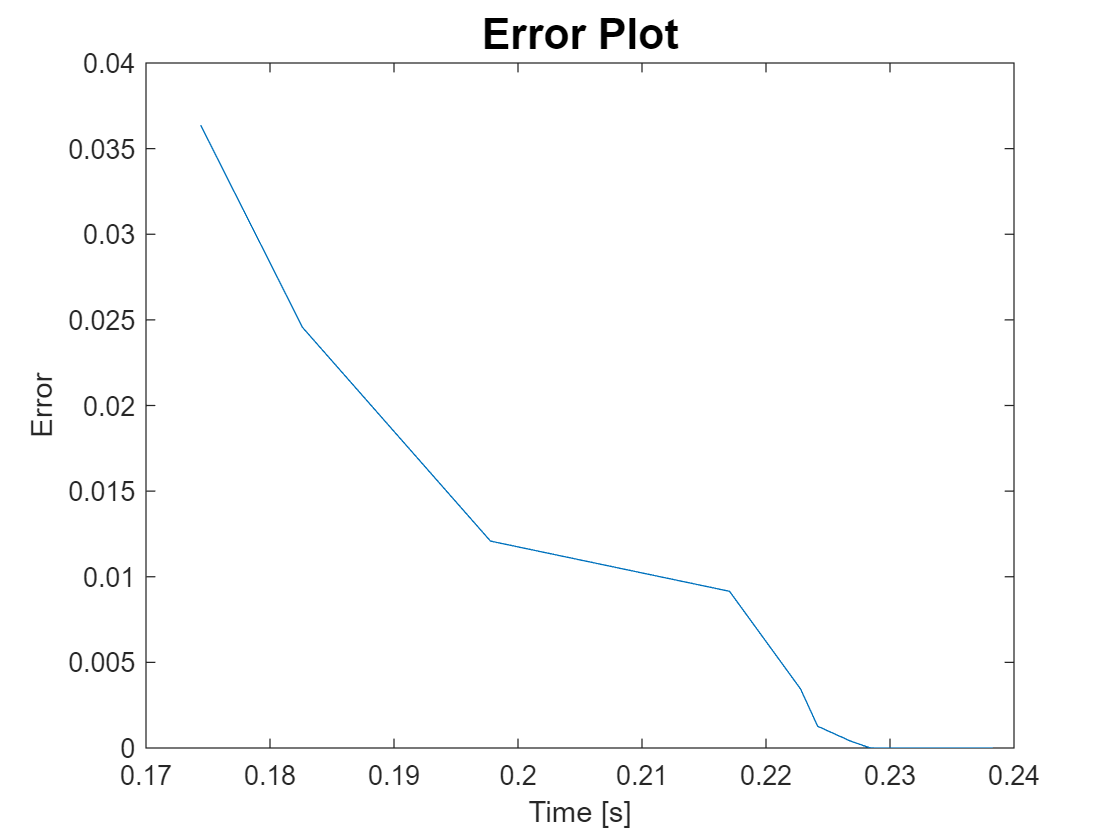

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

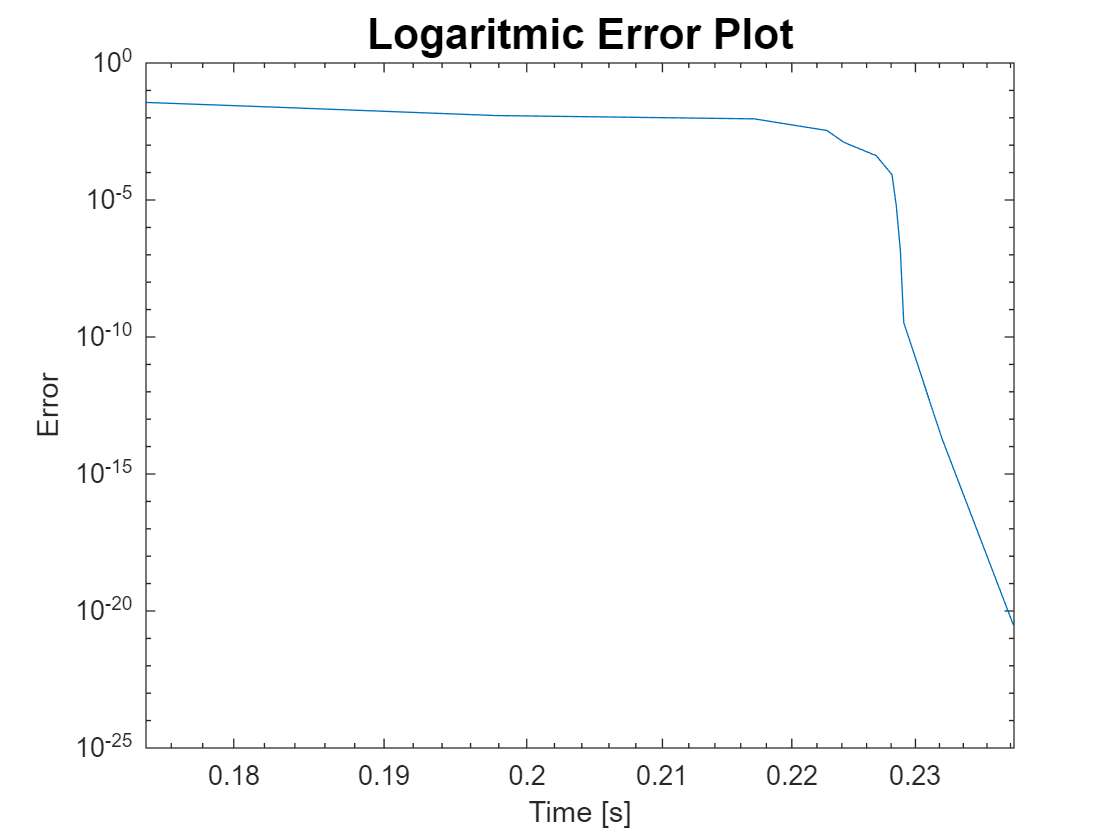

loglog(timeCostseq, err_fseq)
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

#### Plots

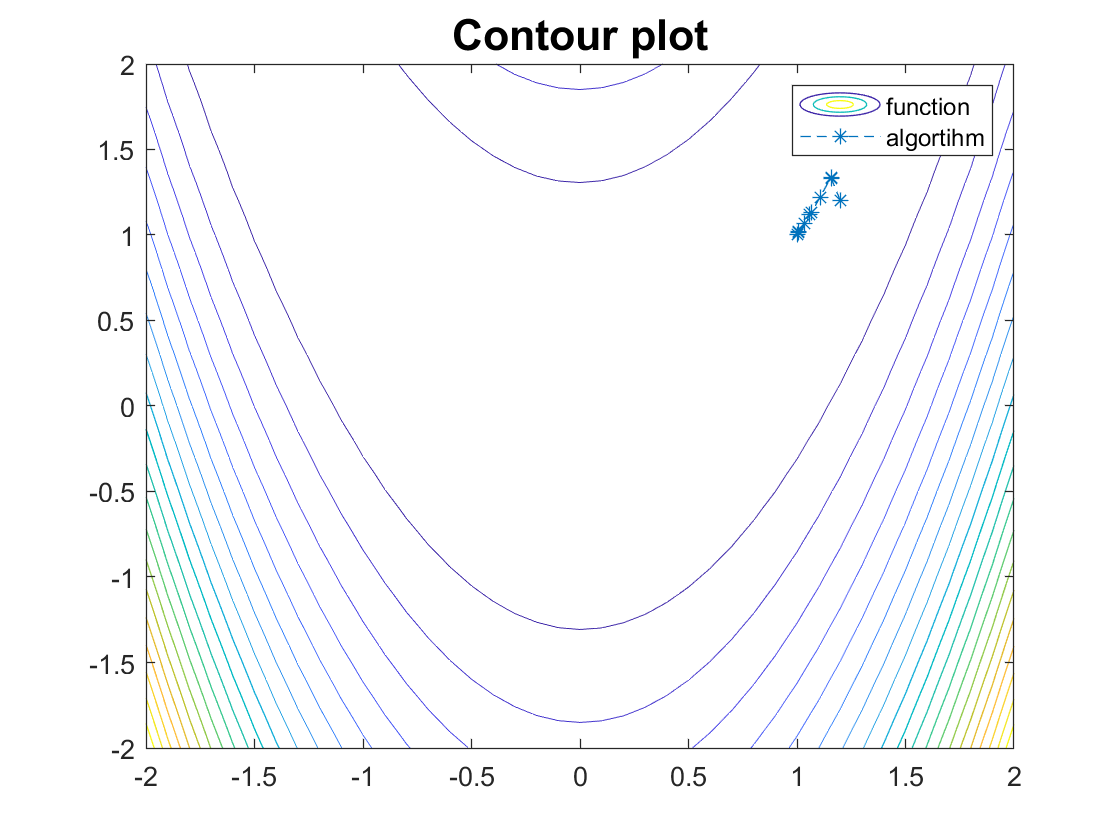

% Preliminaries
x = -2:0.1:2;
y = -2:0.1:2;
[X,Y] = meshgrid(x, y);  % creation of the meshgrid for the contour-plot
f_meshgrid = @(X,Y) reshape(f([X(:),Y(:)]'),size(X));
Z = f_meshgrid(X, Y);  % ("elegant") computation of the values of f for each point of the mesh

% Contour plot
fig1 = figure(); 
contour(X, Y, Z, 20);  % f(xseq)
hold on
title('Contour plot','FontSize',16)
plot([x0(1), xseq(1, :)], [x0(2), xseq(2, :)], '--*') 
legend('function', 'algortihm')
hold off

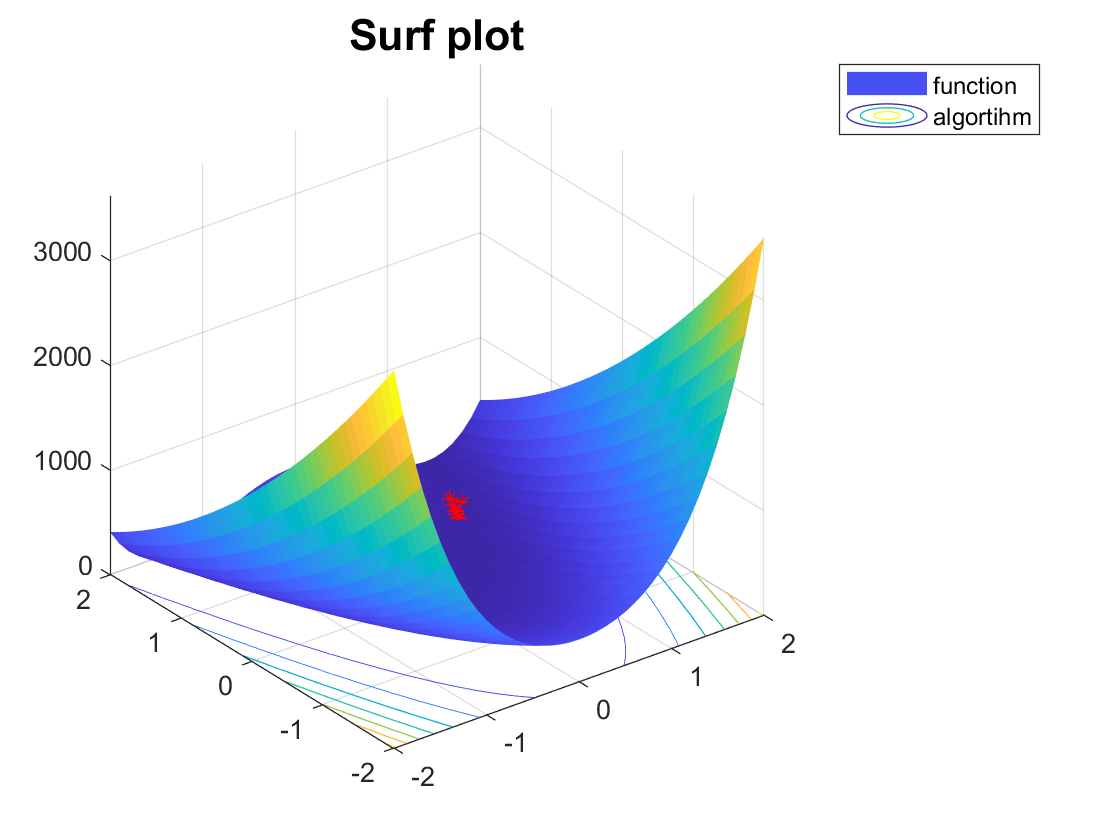

% Surf plot
fig3 = figure();  
surfc(X, Y, Z, 'EdgeColor', 'none')
% shading interp;
% colormap jet
hold on
title('Surf plot','FontSize',16)
plot3([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], [f(x0), f(xseq)], 'r--*')
% colorbar
legend('function', 'algortihm')
hold off